# Exercise 1

## Probabalistic Roadmaps

### About This Exercise

In the previous course, you built graphs based on the shape of the obtacles by either doing cell decomposition or using visiblilty methods based off of the vertices of the obstacles. In this course, instead of using the exact shape of the obstacles, you will only rely on having a function that tells you if a point is in an obstacle. Then you can sample points in some way and use those as nodes so long as they do not fall within an obstacle. In this exercise, you will create a roadmap using this sampling method. You can then use the graph search algorthim developed previously to find a path.

In later exercises, instead of building a whole roadmap to cover the space, you will sample to grow trees from a start point to end point while avoiding obstacles, leaving just one path. Thus, no graph search is needed, as the path is already found.

**By the end of this exercise, you'll be able to: **

- **Create a probabalistic roadmap using random sampling.**

### Random Sampling

This first exercise should feel very familiar, as we are again making a roadmap graph but now using random samples as the nodes. This process is similar to the random initial sampling of the particle filter, only now instead of making sure you're within the boundary of a map, you are making sure the samples fall outside of the boundaries of obstacles.

 [► Complete the function randomSamples](matlab:open('./randomSamples.mlx'))

Again, we need to set up the coordinate of the obstacles. Then we can pass those obstacles into our randomSamples function to retreive nodes that do not fall within the obstacles.

lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

Get the polyvec using makePolyvec.

[polyvec, obstacle] = makePolyvec(obstacle);

M =27;
[nodes_xy] = randomSamples(M,polyvec,lim);

Plot the resulting samples

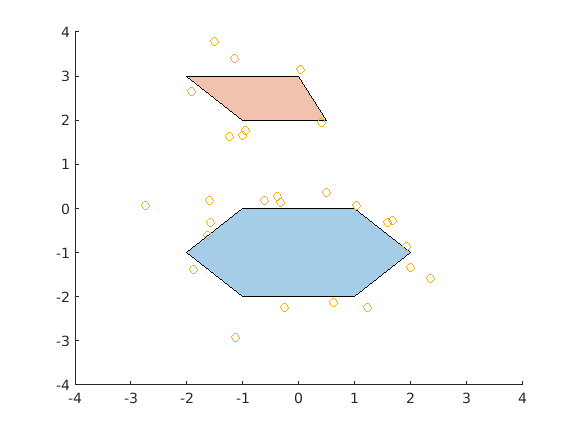

figure
plot(polyvec)
axis([-lim lim -lim lim])
hold on
scatter(nodes_xy(1,:),nodes_xy(2,:))

To get more nodes closer to obstacles, we can use the Gaussian samples. 

[► Complete the gaussianSampler function](matlab:open('./gaussianSampler.mlx')) so we can compare the different sampling methods.

M =8;
[nodes_xy] = gaussianSampler(M,polyvec,lim);

Plot the resulting samples

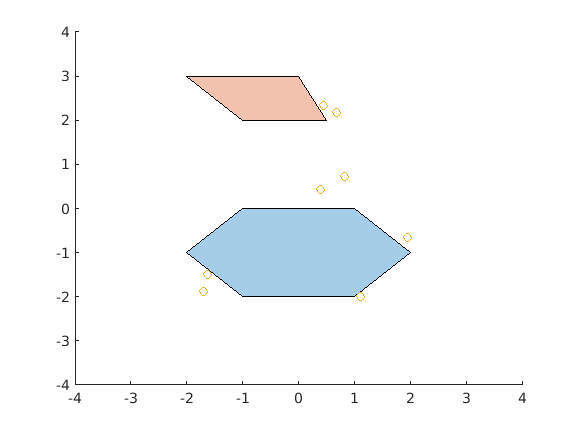

figure
plot(polyvec)
axis([-lim lim -lim lim])
hold on
scatter(nodes_xy(1,:),nodes_xy(2,:))

### Connect

Now that we have randomly sample nodes, we need to connect them somehow. One of the methods given in the videos was the k-nearest-neighbors method. 

[► Complete the connectKNN function](matlab:open('./connectKNN.mlx')), which takes in the node xy-coordinates, the vector of polygon obstacles, and the knn parameter to choose how many neighbors to connect.

knn = 6;
[A, G, H] = connectKNN(nodes_xy, polyvec, knn);

Plot the resulting graph.

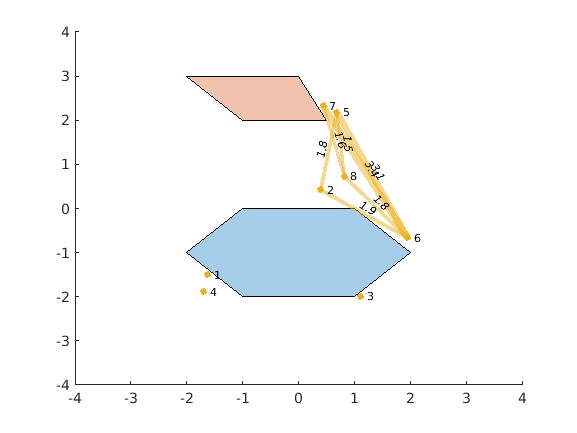

figure
plot(polyvec)
hold on
axis([-lim lim -lim lim])
LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)

Now that we have a graph, we can use the graphSearch function created in the previous course to search for the shortest path on the probabilistic roadmap. (The sliders here go up to 20, but you may have more or fewer nodes)

S = 12;
D = 18;
[path,iterations] = graphSearch(A, S, D, H); % Try using H as the fourth argument

Plot the result

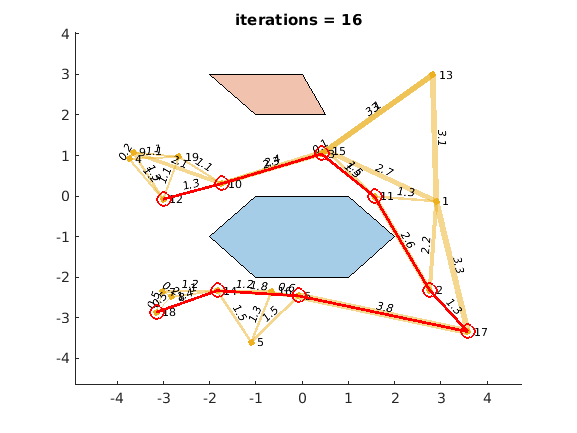

figure
plot(polyvec)
hold on
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)
plot(nodes_xy(1,path),nodes_xy(2,path),'r-o','Markersize',10,'LineWidth',2)
title(['iterations = ' num2str(iterations)])

### Finished!

Now that you have created some graphs using random sampling, how do you think it compares to the deterministic graphs from the previous course? What are the advantages/disadvantages of the two sampling methods? One advantage of course is that we don't need to know exactly what the obstacles are, we just need a function to tell us if a point is in collision. However, we are likely to get nodes that are redundant using pure random sampling without further regards to selection. Here, we also just explored one method of connecting neighbors. In the next exercise, we will be a bit more selective about which nodes we keep, and build the graph as we sample.